clear all

data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;
eye(2)

ans =      1     0
     0     1


G1 = FWT(1:2,1:2)

G1 =
 
  A = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s        -0.422       -0.2204             0       -0.2204             0
   z1dot (m/s)        0.02328      -0.01085         -0.04     -0.009574             0
   z1 (m)                   0             1             0             0             0
   z2dot (m/s)         0.1455      -0.05984             0       -0.1651        -10.82
   z2 (m)                   0             0             0             1             0
 
  B = 
                 Beta (deg)  tau_e (Nm)
   Omega (rad/s    -0.07988   -0.009564
   z1dot (m/s)    -0.006722           0
   z1 (m)                 0           0
   z2dot (m/s)     -0.04202           0
   z2 (m)                 0           0
 
  C = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s            -1             0             0             0             0
   z (m)                    0           

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = G1.C*inv((s*eye(5)-G1.A))*G1.B

G =
 
  From input 1 to output...
                                                                                             
       0.07988 s^14 + 0.09884 s^13 + 2.654 s^12 + 2.906 s^11 + 29.62 s^10 + 28.22 s^9        
                                                                                             
               + 114.1 s^8 + 91.37 s^7 + 33.67 s^6 + 11.32 s^5 + 2.878 s^4 + 0.4741 s^3      
                                                                                             
                                                        + 0.09734 s^2 + 0.006633 s + 0.001154
                                                                                             
   1:  --------------------------------------------------------------------------------------
                                                                                             
       s^15 + 1.794 s^14 + 34 s^13 + 53.72 s^12 + 391.7 s^11 + 533.8 s^10 + 1611 s^9         
                          

omega = [0, 0.6*pi];
    for i =1:length(omega)
        Gf=freqresp(G,omega(i));
        RGAw(:,:,i)=Gf.*inv(Gf).';
        RGAno(i)=sum(sum(abs(RGAw(:,:,i)-eye(2))));
        
    end
    RGA = frd(RGAw,omega)

RGA =

  From input 1 to:

    Frequency(rad/s)         output 1          output 2    
    ----------------         --------          --------    
         0.0000         -0.6554 + 0.0000i  1.6554 + 0.0000i
         1.8850         -0.0283 + 0.1398i  1.0283 - 0.1398i

  From input 2 to:

    Frequency(rad/s)        output 1           output 2    
    ----------------        --------           --------    
         0.0000         1.6554 + 0.0000i  -0.6554 + 0.0000i
         1.8850         1.0283 - 0.1398i  -0.0283 + 0.1398i
 
Continuous-time frequency response.



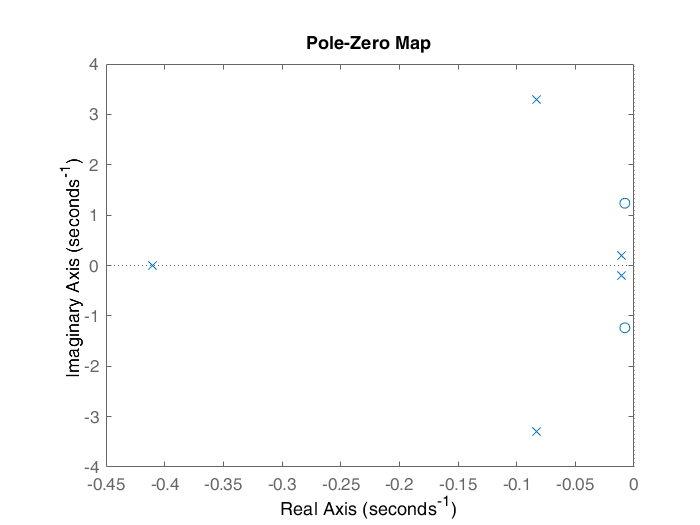

pzplot(FWT(1:2,1:2))

poles = pole(FWT(1:2,1:2))

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


zeros = zero(FWT(1:2,1:2))

zeros =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i
